# Code to evualute $P_{r_\mathrm{in}}(T_\mathrm{out}<T_\mathrm{upd})$

### Evaluating $$P_{J\mathrm{out}}$$


$$P_{J\mathrm{out}}(j)=\left(\frac{A_\mathrm{in}}{A}\right)^j\left(1-\frac{A_\mathrm{in}}{A}\right)$$


J=7;%total of convolutions and jumps
j =1:J;

r_select=1;%radius selection for plotting

r_A=r_inner/r_outer;%ratio of areas
% r_A=[10 30 50]/100;%ratio of areas
P_j_out=zeros(length(r_A),J);
init_point=0;
end_point=length(j);

for r=1:length(r_A)
    P_j_out(r,:)=r_A(r).^(j-1)*(1-r_A(r));    
end


% figure;
% color = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#4DBEEE','#A2142F'}; %list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html
% line_width=linspace(1,3,length(color));%specify the width for each line in the plot
% marker={'-','-+','-d','-.','-x','-o','-s','-*','-|','-^'};% marker symbols are given at https://www.mathworks.com/help/matlab/creating_plots/create-line-plot-with-markers.html
% marker_size=1:length(color);%specify the width for each marker in the plot
% marker_indices=1:length(color);%specify the length between markers
% 
% total_curves=3;
% step=round(length(r_A)/total_curves);
% m=1;
% for r=1:step:length(r_A)
%     plot(j,P_j_out(r,:),marker{m},'Color',color{m},'LineWidth',line_width(length(color)-m+1),...
%         'MarkerEdgeColor',color{m},'MarkerFaceColor',color{m});hold on;
%     m=m+1;
% end
% 
% grid on;
% 
% r=1:total_curves;
% legend_text=cell(1,length(r));
% for m=1:length(r)
%   legend_text{m}=strcat('$\frac{A_c}{A}=',num2str(r_A(r(m))*100,2),'$\%');
% end
% 
% legend({legend_text{:}},...
%     'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
% grid on;
% hold off %to close the canvas
% 
% xlabel('Jumps $(j)$','Interpreter','latex');
% ylabel('$P_{J\mathrm{out}}(j)$','Interpreter','latex');
% set(gca,'FontSize',fontsize);
% axis([1 j(end) 0 1.1*max(max(P_j_out))]);

### Evaluating $f_{\tau_j;r_\mathrm{in}}}$


$$f_{\tau_j;r_\mathrm{in}}=vf_{L}(v\!\tau_j;r_\mathrm{in})$$


where


$$f_{L}(l_j)=\frac{8}{\pi r_\mathrm{in}}\frac{l_j}{2r_\mathrm{in}}\left(\arccos\frac{l_j}{2r_\mathrm{in}}-\frac{l_j}{2r_\mathrm{in}}\sqrt{1-\left(\frac{l_j}{2r_\mathrm{in}}\right)^2}\right)$$


% delta_tau_j=0.1;
f_tau_j=cell(1,length(r_inner));


for j=1:length(r_inner)
    tau_j=0:delta_tau_j:2*r_inner(j)/v;
    f_tau_j{j}=v*8/(pi*r_inner(j))*v*tau_j/(2*r_inner(j)).*(acos(v*tau_j/(2*r_inner(j)))-(v*tau_j/(2*r_inner(j))).*sqrt(1-(v*tau_j/(2*r_inner(j))).^2));
end

### Evaluating $f_{T_\mathrm{out}}(t_\mathrm{out}|j)$ for a given inner circle radius $r_{\textrm{in}}$


$$f_{T_\mathrm{out}}(t_\mathrm{out}|j)=
    \underbrace{f_{\tau_j;r_\mathrm{in}}\ast \cdots \ast f_{\tau_j;r_\mathrm{in}}}_{j}\big|_{\tau_j=t_\mathrm{out}}$$


% evaluating the N-fold convolution
f_tau=cell(length(r_inner),J);

for r=1:length(r_inner)
    f_tau{r,1}=f_tau_j{r};
    for j=2:J
        f_tau{r,j}=conv(f_tau{r,j-1},f_tau_j{r})*delta_tau_j;
    end
end

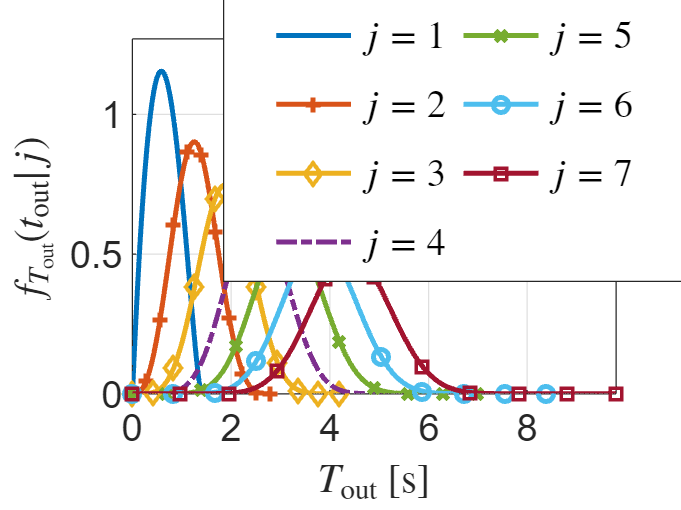

% r_select=length(r_inner);
% figure;
% total_curves=7;
% step=ceil(J/total_curves);
% r=1:step:J;
% 
% for j=1:total_curves
%     tau=(0:length(f_tau{r_select,r(j)})-1)*delta_tau_j;
%     plot(tau,f_tau{r_select,r(j)},marker{j},'Color',color{j},...
%         'LineWidth',2,'MarkerIndices',1:round(length(tau)/10):length(tau)); hold on;
% end
% grid on;
% 
% legend_text=cell(1,length(r));
% for m=1:floor(length(r))
%   legend_text{m}=strcat('$j=',num2str(r(m),2),'$');
% end
% 
% legend({legend_text{:}},...
%     'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
% grid on;
% hold off %to close the canvas
% 
% legend("Position", [0.44859,0.5482,0.44286,0.3619]);
% xlabel('$T_\mathrm{out}$ [s]','Interpreter','latex');
% ylabel('$f_{T_\mathrm{out}}(t_\mathrm{out}|j)$','Interpreter','latex');
% set(gca,'FontSize',fontsize);
% axis([0 tau(end) 0 1.1*max(f_tau{r_select,1})]);

### Evaluating $P_\mathrm{in}(T_\mathrm{out}|j)$


$$P_\mathrm{in}(T_\mathrm{out}|j)=\int_0^{T_\mathrm{out}}{f_{T_\mathrm{out}}(t_\mathrm{out}|j)\mathrm{d}t_\mathrm{out}}$$


P_T_out_j=cell(length(r_inner),J);

for r=1:length(r_inner)
    for j=1:J
        P_T_out_j{r,j}=horzcat(cumtrapz(f_tau{r,j})*delta_tau_j,ones(1,length(f_tau{r,end})-length(f_tau{r,j})));
    end
end



### Evaluating $P_\mathrm{fh\_out}(T_\mathrm{out}<T_\mathrm{upd})$ and $P_{r_\mathrm{in}}(T_\mathrm{out}<T_\mathrm{upd})$

where


$$P_\mathrm{fh\_out}(T_\mathrm{out}<T_\mathrm{upd})=\sum_{j=1}^\infty {P(T_\mathrm{out}|j)P_{J\mathrm{out}}(j)}$$


and


$$P_{r_\mathrm{in}}(T_\mathrm{out}<T_\mathrm{upd})=1-P_\mathrm{fh\_out}(T_\mathrm{out}<T_\mathrm{upd})$$



P_fh_out=zeros(length(r_inner),length(P_T_out_j{end}));


for r=1:length(r_inner)
    for j=1:J
        P_fh_out(r,:)=P_fh_out(r,:)+horzcat(P_T_out_j{r,j}*P_j_out(r,j),zeros(1,length(P_T_out_j{end,end})-length(P_T_out_j{r,j})));        
    end
end

P_r_in=1-P_fh_out;